p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:20


Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 30 workers.


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:20


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:14.2857


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:16.6667


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:16.6667


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:20


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


success


%assemblées meme couleur:28.5714


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:20


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


success


%assemblées meme couleur:28.5714


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


success


success
%assemblées meme couleur:42.8571


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


success


%assemblées meme couleur:28.5714


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:50


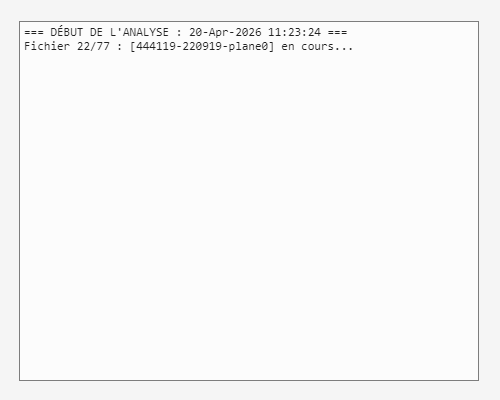

p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:50


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:25


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:25


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


success


%assemblées meme couleur:40


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:25


p =   1×16 graphics array:

    Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text     Patch    Text 


success


%assemblées meme couleur:20


clear
close all

dossier_principal = "E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220919_plane0_26_04_20_11_23_24\";
% dossier_principal = "E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220922_plane0_26_04_21_08_22_36\";
% dossier_principal = "E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220923_plane0_26_04_21_08_29_46\";
% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220922\registration\colorcell.mat"; %colorcell Solene
% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220923\registration\colorcell.mat"; 
path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validated_20260424.mat"; 
motif_recherche = '*k*';

contenu = dir(fullfile(dossier_principal, motif_recherche));
dossiers_trouves = contenu([contenu.isdir]); % Garder uniquement les dossiers

nb_analyses_initial = length(dossiers_trouves);
vars_to_load = {'daytime', 'identifier', 'NRace', 'freqsce', 'NRaceOK', 'freqsceok', ...
        'assemblyortho', 'sCl','NCl','NClOK','mean_sClOK',  'idortho', ...
        'mean_cell_assembly', 'NCell', 'Nz', 'sampling_rate', 'WinRest', ...
        'average_speed', 'max_speed', 'nb_lap', 'sce_n_cells_threshold',  ...
        'kmeans_surrogate', 'file_num','NClini','path','Cl0' ,'Cl1', 'Cl2',... 
        'Cl3','x1','Race','PCl_final','TRace','speed','Tr1b'};

for d = 1:nb_analyses_initial
    noms_analyses{d} = dossiers_trouves(d).name;
    fichier = fullfile(dossier_principal, noms_analyses{d}, 'results.mat');

    % load(fichier,vars_to_load{:});
    if isfile(fichier)
        load(fichier,'NCl');
        %namefull = strcat(PathSave ,identifier ,'_',daytime  ,'\');%pc
    
    
        if NCl>1  
            load(fichier);
            namefull = fullfile(dossier_principal, 'colorexvivovalidated',noms_analyses{d},'\');
            mkdir (namefull) ;
            brainbowassemblies2025_11_26
            rastercolor
            graphSCE
            distance_calculation
            export_data_brainbow
            save(strcat(namefull,'brainbow.mat') )
        end
    end
end